# Frequency Based control design of the horizontal arm

clear 
close all 

parametri = 1;      % 0 = nominali; 1 = identificati

## System parameters

if parametri == 0
    B_p = 0.0024; % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = 0.0024; % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = 0.0020; % Rotary arm moment of inertia about pivot m^2
    J_p = 0.0012; % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = 0.156;  % Distance from pivot to center of mass m
    m_p = 0.127;  % Mass of pendulum Kg
    r = 0.216;    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = 9.81;     % gravitational acceleration m/s^2

    K_g = 70;      % High-gear total gear ratio
    R_m = 2.6;     % Ohm
    eta_g = 0.90;  % Gearbox efficiency
    eta_m = 0.69;  % Motor efficiency
    k_m = 7.68e-3; % Motor back-emf constant V/(rad/s)
    k_t = 7.68e-3; % Motor current-torque constant N*m/A
else
    % Valori identificati
    load th_id
    B_p = id_param(1); % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = id_param(2); % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = id_param(3); % Rotary arm moment of inertia about pivot m^2
    J_p = id_param(4); % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = id_param(5);  % Distance from pivot to center of mass m
    m_p = id_param(6);  % Mass of pendulum Kg
    r = id_param(7);    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = id_param(8);     % gravitational acceleration m/s^2

    K_g = id_param(9);      % High-gear total gear ratio
    R_m = id_param(10);     % Ohm
    eta_g = id_param(11);  % Gearbox efficiency
    eta_m = id_param(12);  % Motor efficiency
    k_m = id_param(13); % Motor back-emf constant V/(rad/s)
    k_t = id_param(14); % Motor current-torque constant N*m/A
end

theta_max = 90;     % +- Maximum theta rotation [deg]
voltage_max = 10;   % Maximum control voltage

## PID tuner settings

type = 'pi';        % Opzioni: p pi pid
BW = 4.04;          % Bandwidth
PM = 90;            % Phase Margin

## Open Loop system Analysis

### Build the state space matrices

[A,B,C,D] = SS_Matrices_Voltage_Stable(B_p,B_r,J_T,J_a,J_p,K_g,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);
C = eye(4);
D = zeros(4,1);

% State-space model
ss_sys = ss(A,B,C,D);

% Transfer functions
tf_sys = tf(ss_sys)

tf_sys =
 
  From input to output...
            27.22 s^2 + 12.45 s + 1155
   1:  -------------------------------------
       s^4 + 17.04 s^3 + 55.99 s^2 + 700.6 s
 
             -25.42 s + 3.992e-15
   2:  ---------------------------------
       s^3 + 17.04 s^2 + 55.99 s + 700.6
 
          27.22 s^2 + 12.45 s + 1155
   3:  ---------------------------------
       s^3 + 17.04 s^2 + 55.99 s + 700.6
 
       -25.42 s^2 + 9.953e-16 s + 1.534e-13
   4:  ------------------------------------
        s^3 + 17.04 s^2 + 55.99 s + 700.6
 
Continuous-time transfer function.



% controlSystemDesigner(tf_sys(1)) % open system designer app

### O.L. Transfer Function Anlysis 

### $G_{V\theta \;} \left(s\right)$:

G_th = tf_sys(1)

G_th =
 
       27.22 s^2 + 12.45 s + 1155
  -------------------------------------
  s^4 + 17.04 s^3 + 55.99 s^2 + 700.6 s
 
Continuous-time transfer function.



% Nyquist form
sys = zpk(G_th)

sys =
 
    27.221 (s^2 + 0.4572s + 42.42)
  -----------------------------------
  s (s+16.25) (s^2 + 0.7921s + 43.12)
 
Continuous-time zero/pole/gain model.



sys.DisplayFormat='frequency';  
% Bode form
sys

sys =
 
     1.6481 (1 + 0.0702(s/6.513) + (s/6.513)^2)
  -------------------------------------------------
  s (1+s/16.25) (1 + 0.1206(s/6.567) + (s/6.567)^2)
 
Continuous-time zero/pole/gain model.



poles_G_th = eig(G_th)

poles_G_th =    0.0000 + 0.0000i
 -16.2465 + 0.0000i
  -0.3960 + 6.5549i
  -0.3960 - 6.5549i


zeros_G_th= zero(G_th)

zeros_G_th =   -0.2286 + 6.5090i
  -0.2286 - 6.5090i


gain_G_th = dcgain(G_th)

gain_G_th = Inf

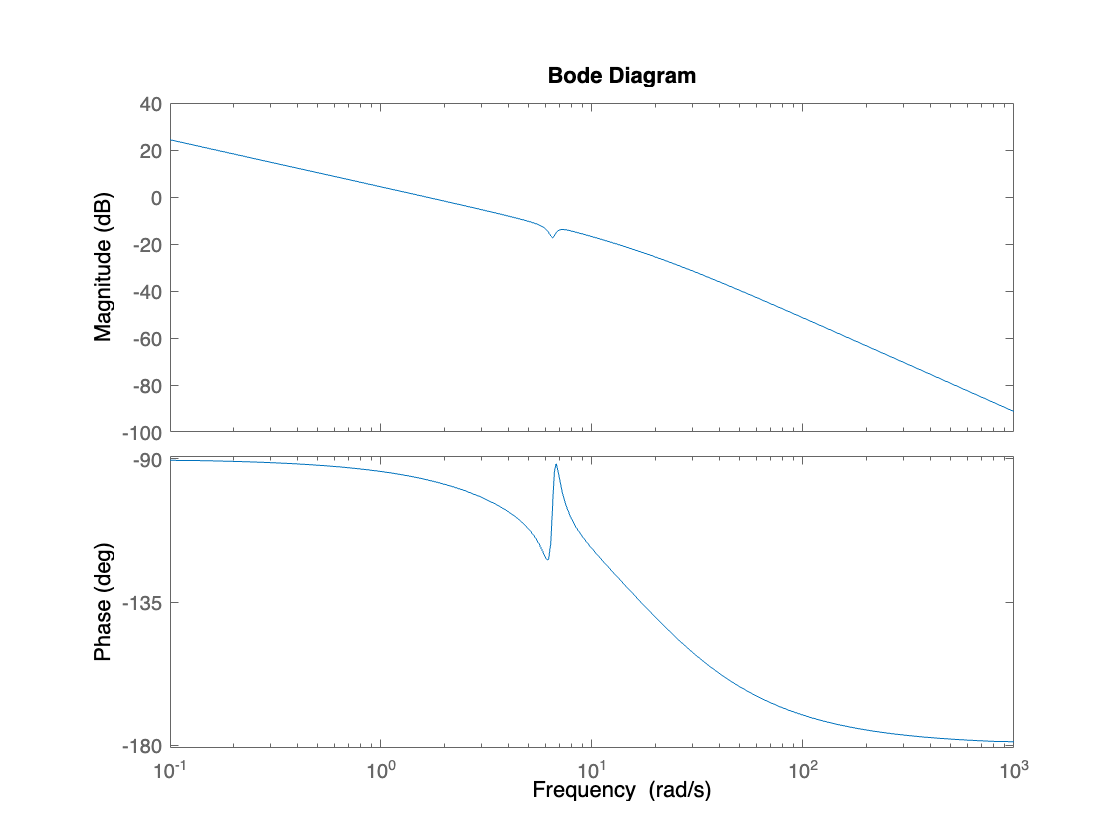

bode(G_th)

[Gm_th,Pm_th,Wcg_th,Wcp_th] = margin(G_th)

Gm_th = Inf

Pm_th = 83.4873

Wcg_th = Inf

Wcp_th = 1.6374

### 
$$G_{V\alpha \;} \left(s\right)$$


G_alpha = tf_sys(2)

G_alpha =
 
        -25.42 s + 3.992e-15
  ---------------------------------
  s^3 + 17.04 s^2 + 55.99 s + 700.6
 
Continuous-time transfer function.



poles_G_alpha = eig(G_alpha)

poles_G_alpha =  -16.2465 + 0.0000i
  -0.3960 + 6.5549i
  -0.3960 - 6.5549i


zeros_G_alpha = zero(G_alpha)

zeros_G_alpha = 1.5701e-16

gain_G_alpha = dcgain(G_alpha)

gain_G_alpha = 5.6976e-18

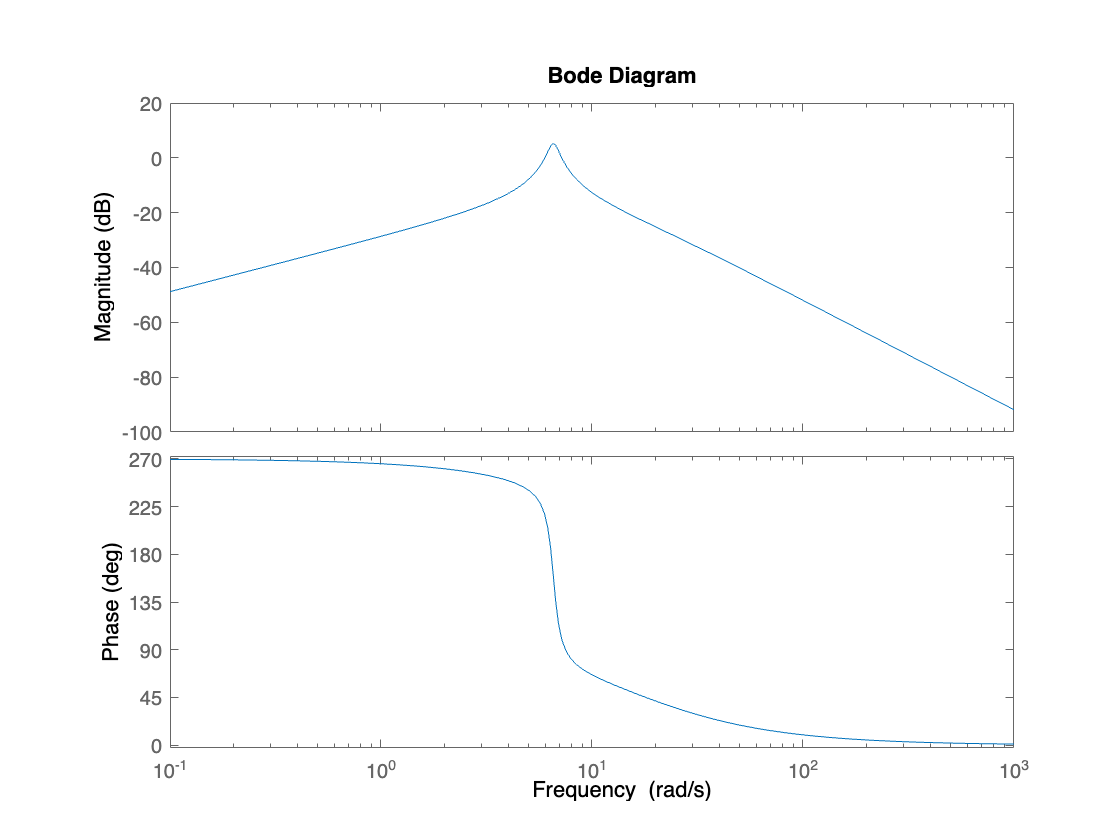

bode(G_alpha)

[Gm_alpha,Pm_alpha,WcG_alpha,Wcp_alpha] = margin(G_alpha)

Gm_alpha = 0.5850

Pm_alpha = 37.1616

WcG_alpha = 6.4124

Wcp_alpha = 5.9776

### 
$$G_{V\dot{\theta} } \left(s\right)$$


G_th_dot = tf_sys(3)

G_th_dot =
 
     27.22 s^2 + 12.45 s + 1155
  ---------------------------------
  s^3 + 17.04 s^2 + 55.99 s + 700.6
 
Continuous-time transfer function.



% Nyquist form
sys = zpk(G_th_dot)

sys =
 
   27.221 (s^2 + 0.4572s + 42.42)
  ---------------------------------
  (s+16.25) (s^2 + 0.7921s + 43.12)
 
Continuous-time zero/pole/gain model.



sys.DisplayFormat='frequency';  
% Bode form
sys

sys =
 
    1.6481 (1 + 0.0702(s/6.513) + (s/6.513)^2)
  -----------------------------------------------
  (1+s/16.25) (1 + 0.1206(s/6.567) + (s/6.567)^2)
 
Continuous-time zero/pole/gain model.



poles_G_th_dot = eig(G_th_dot)

poles_G_th_dot =  -16.2465 + 0.0000i
  -0.3960 + 6.5549i
  -0.3960 - 6.5549i


zeros_G_th_dot= zero(G_th_dot)

zeros_G_th_dot =   -0.2286 + 6.5090i
  -0.2286 - 6.5090i


gain_G_th_dot = dcgain(G_th_dot)

gain_G_th_dot = 1.6481

bode(G_th_dot)
bw = bandwidth(G_th_dot)

bw = 6.1569

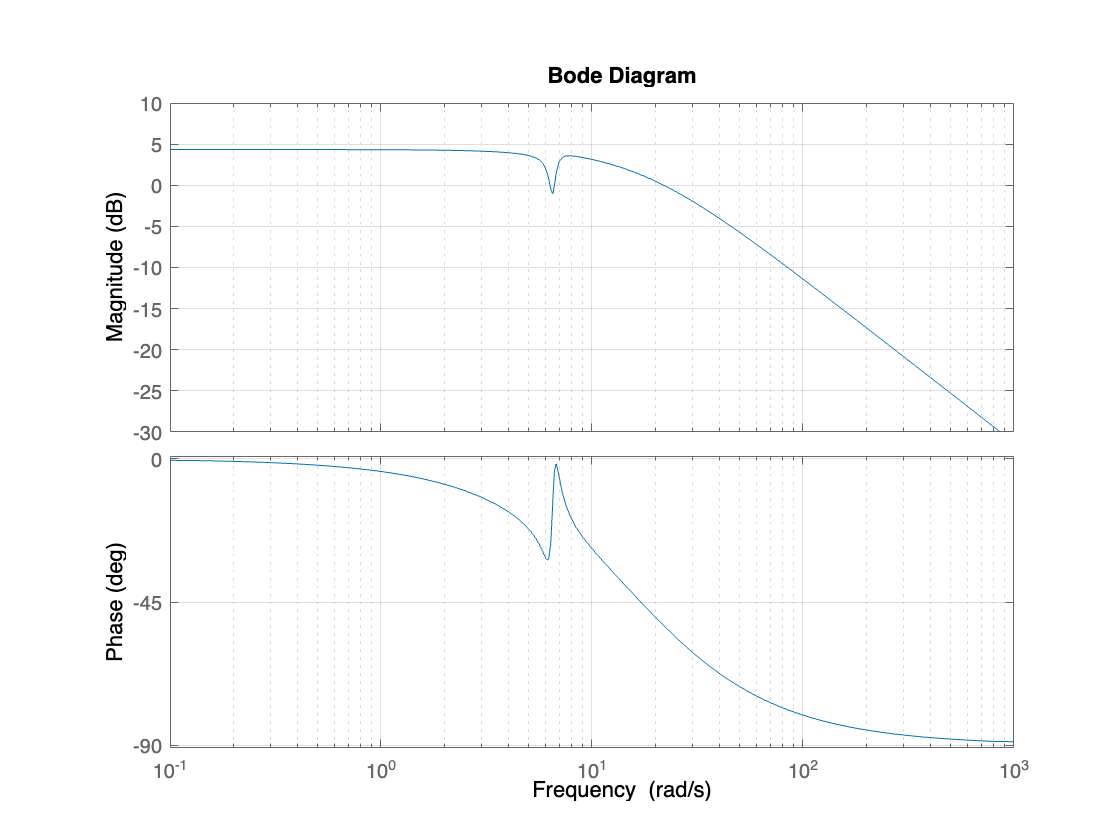

grid on

[Gm_th_dot,Pm_th_dot,Wcg_th_dot,Wcp_th_dot] = margin(G_th_dot)

Gm_th_dot = Inf

Pm_th_dot = 127.5625

Wcg_th_dot = NaN

Wcp_th_dot = 21.8779

### 
$$G_{V\dot{\alpha} } \left(s\right)$$


G_alpha_dot = tf_sys(4)

G_alpha_dot =
 
  -25.42 s^2 + 9.953e-16 s + 1.534e-13
  ------------------------------------
   s^3 + 17.04 s^2 + 55.99 s + 700.6
 
Continuous-time transfer function.



poles_G_alpha_dot = eig(G_alpha_dot)

poles_G_alpha_dot =  -16.2465 + 0.0000i
  -0.3960 + 6.5549i
  -0.3960 - 6.5549i


zeros_G_alpha_dot = zero(G_alpha_dot)

zeros_G_alpha_dot = 1.0e-07 *

    0.7769
   -0.7769


gain_G_alpha_dot = dcgain(G_alpha_dot)

gain_G_alpha_dot = 2.1902e-16

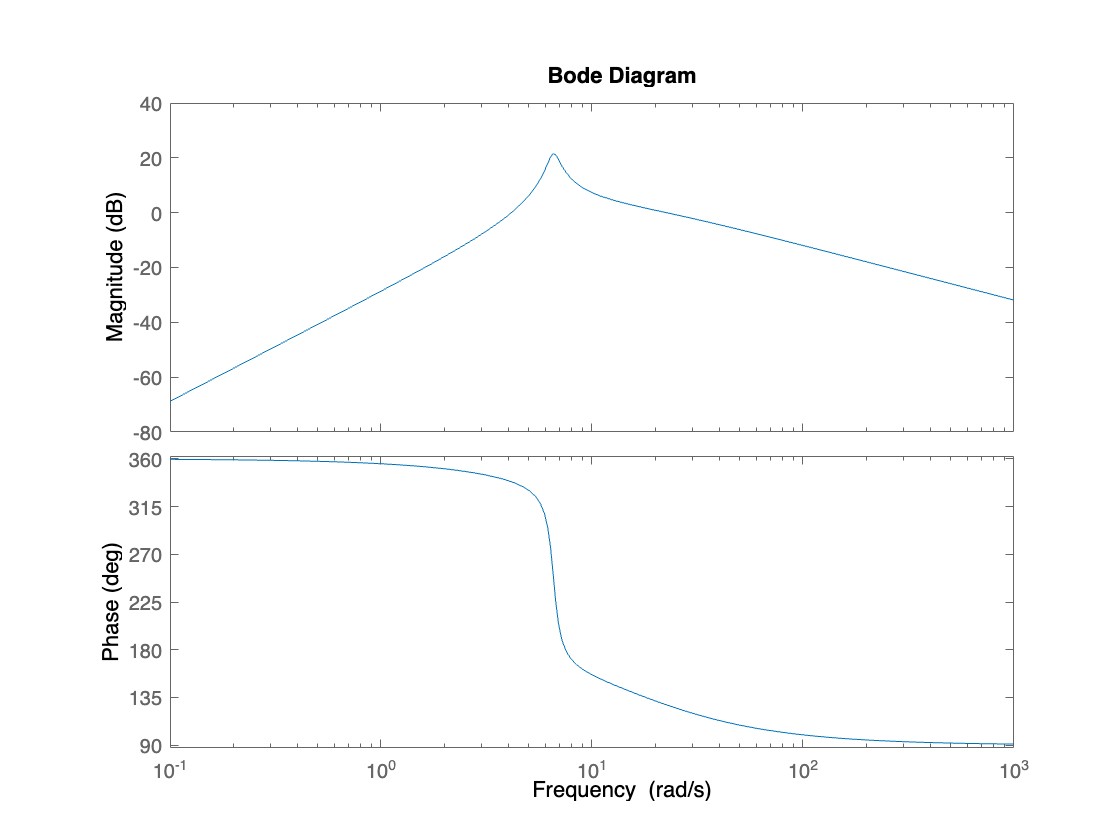

bode(G_alpha_dot)

[Gm_alpha_dot,Pm_alpha_dot,WcG_alpha_dot,Wcp_alpha_dot] = margin(G_alpha_dot)

Gm_alpha_dot = 0.1781

Pm_alpha_dot = -51.9880

WcG_alpha_dot = 7.4834

Wcp_alpha_dot = 22.5178

## Bandwidth of the system

Computed from $\dot{\;\theta }$ frequency response is approximately $5\ldotp 61\;\frac{\textrm{rad}}{s}$.

## PID tuner

% pidTuner(ss_sys(1),'p')

% Compute the gain for the PID controller
opts = pidtuneOptions('CrossoverFrequency',BW,'PhaseMargin',PM);
[G, info] = pidtune(ss_sys(1), type, opts);
% [G, info] = pidtune(tf_sys(1), type, opts);
Kp = G.Kp;      % Proportional gain
Ki = G.Ki;      % Integral gain
Kd = G.Kd;      % Derivative gain
% controlSystemDesigner(tf_sys(1)) Strictly proper

## Compensator

Per velocizzare il sistema di controllo potremmo mettere i wpoli reali dominanti coincidenti (es. -50) da provare

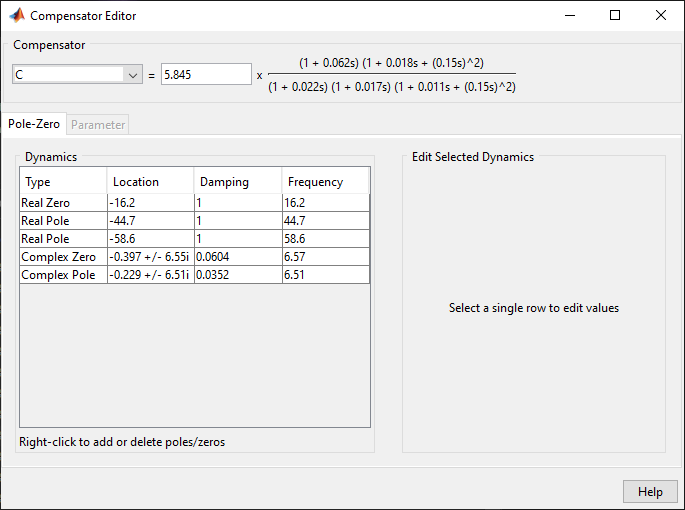

La funzione di trasferimento G(s) dalla tensione all'angolo theta è a.s. quindi usiamo Bode per la stabilità del sistema retroazionato:

- 
$$\mu_L >0$$


- 
$$\phi_M >0$$


- $L\left(s\right)$ interseca l'asse a 0 dB una sola volta

Specifiche (statiche) desiderate sono:

- 
$$e_{\infty } =0$$


Specifiche (dinamiche) desiderate sono

Step responce:

- Rise time (from 10% to 90%) = 0.2 sec

- Settling time ( $e<0\ldotp 02*|\;y_{\textrm{final}} -y_{\textrm{initial}} \;|$ ) =  0.3 sec

- Overshoot (%) $\left(\frac{y_{\max } -y_{\textrm{final}} }{y_{\textrm{final}} }*100\right)$= 5%

Progetto del regolatore:

- Cancellato tutti i poli e gli zeri del sistema (nessuna cancellazione critica), a parte l'integratore (polo nell'origine, errore asintotico nullo)

- Posizionato due poli reali a frequenze tali da rispettare i design requirements dello step responce 

In questo modo il sistema si comporterà come un sistema del terzo ordine (o del secondo ordine con azione integrale).

Tramite il root locus abbiamo poi tarato il guadagno del controllore per evitare la saturazione, all'interno di un range di frequenze.

Per il tuning del gain, abbiamo cercato di mantenere la tensione che diamo in ingresso all'attuatore entro i limiti di saturazione, in una banda fino a 10 rad/s 

## Performances:

Step responce:

- Rise time (from 10% to 90%) = 0.145 sec

- Settling time ( $e<0\ldotp 02*|\;y_{\textrm{final}} -y_{\textrm{initial}} \;|$ ) =  0.236 sec

- Overshoot (%) $\left(\frac{y_{\max } -y_{\textrm{final}} }{y_{\textrm{final}} }*100\right)$= 0.676%

- Peak time = 0.329 sec

Closed loop characteristics:

- Gain margin (G.M.) = 20.6 dB at 51.2 rad/s

- Phase margin = 69.2 deg at $\omega_c =$9.32 rad/s

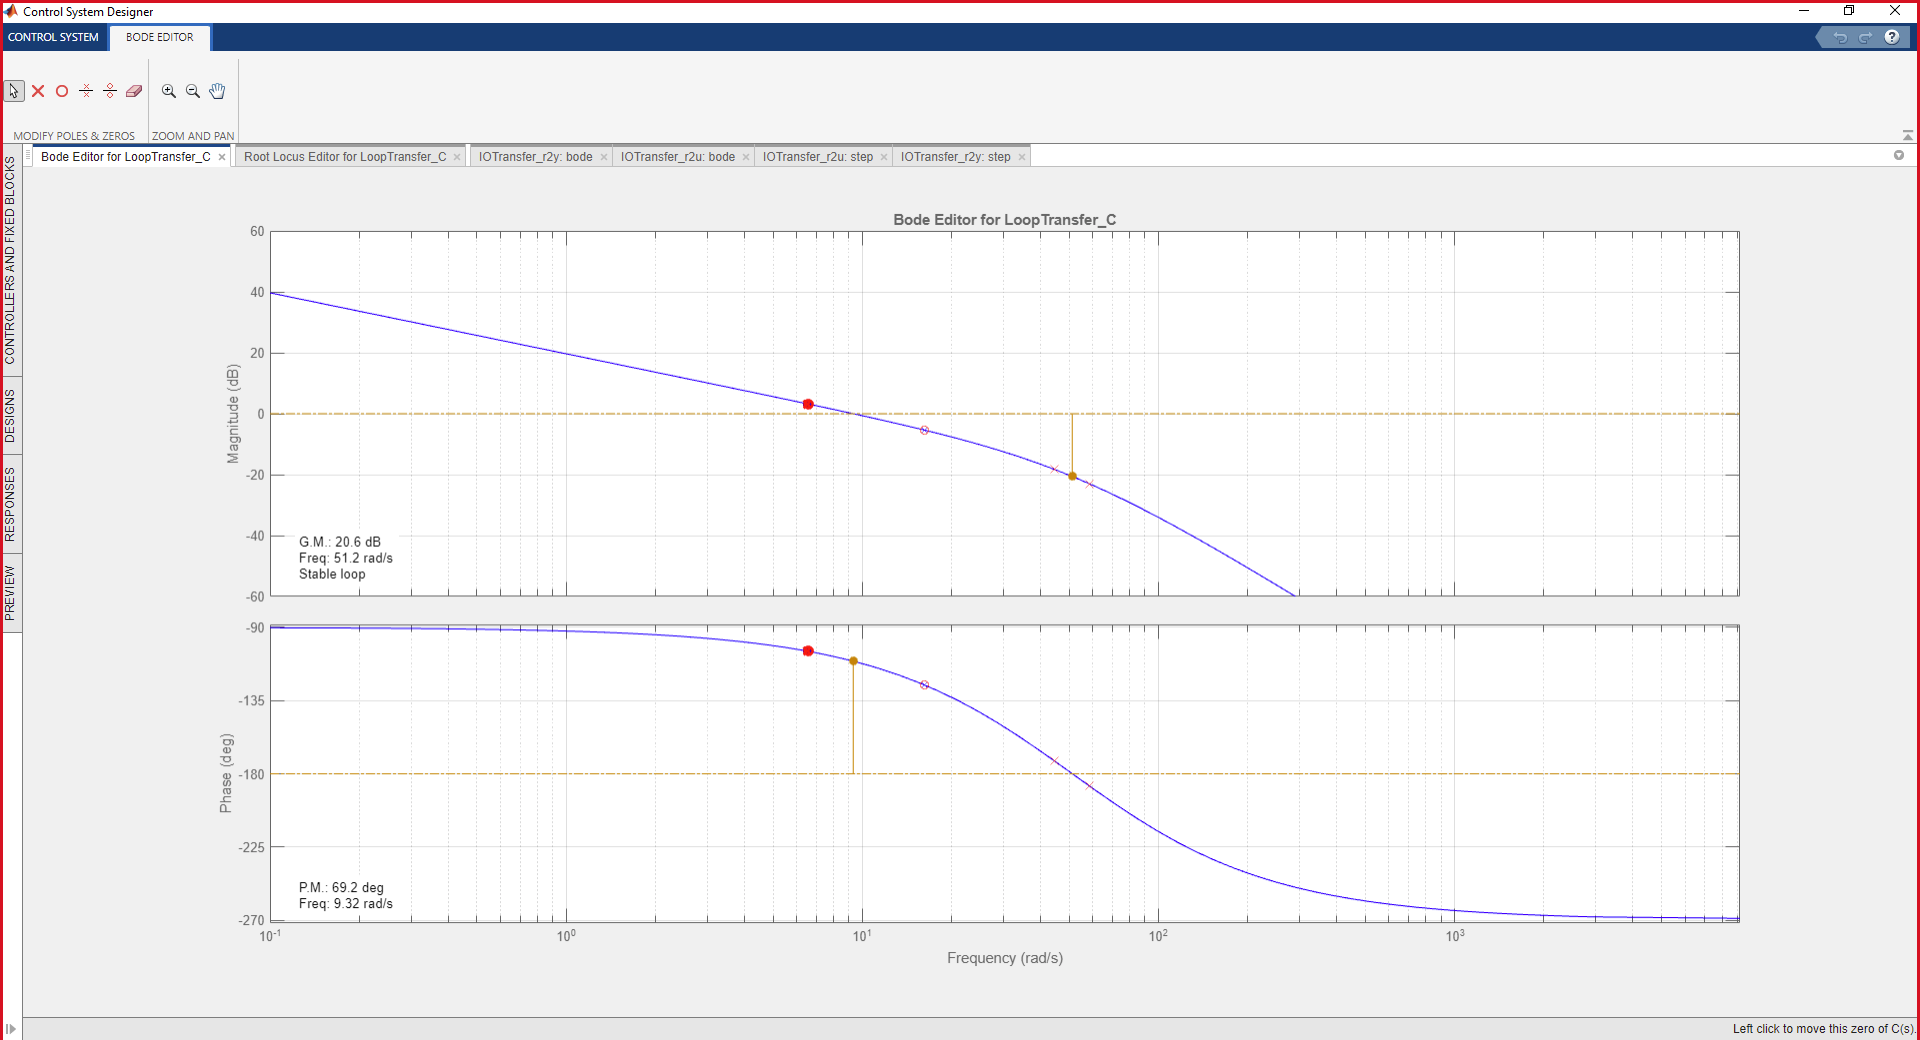

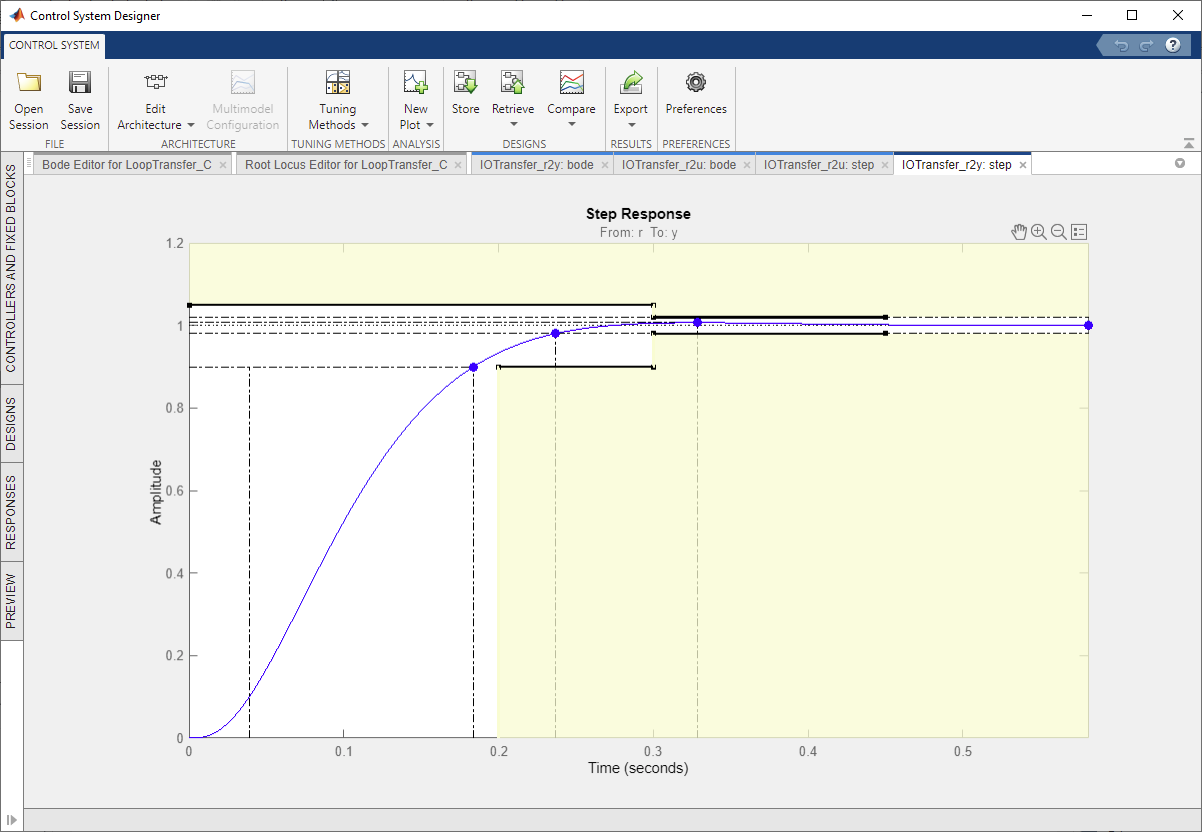

F(s): 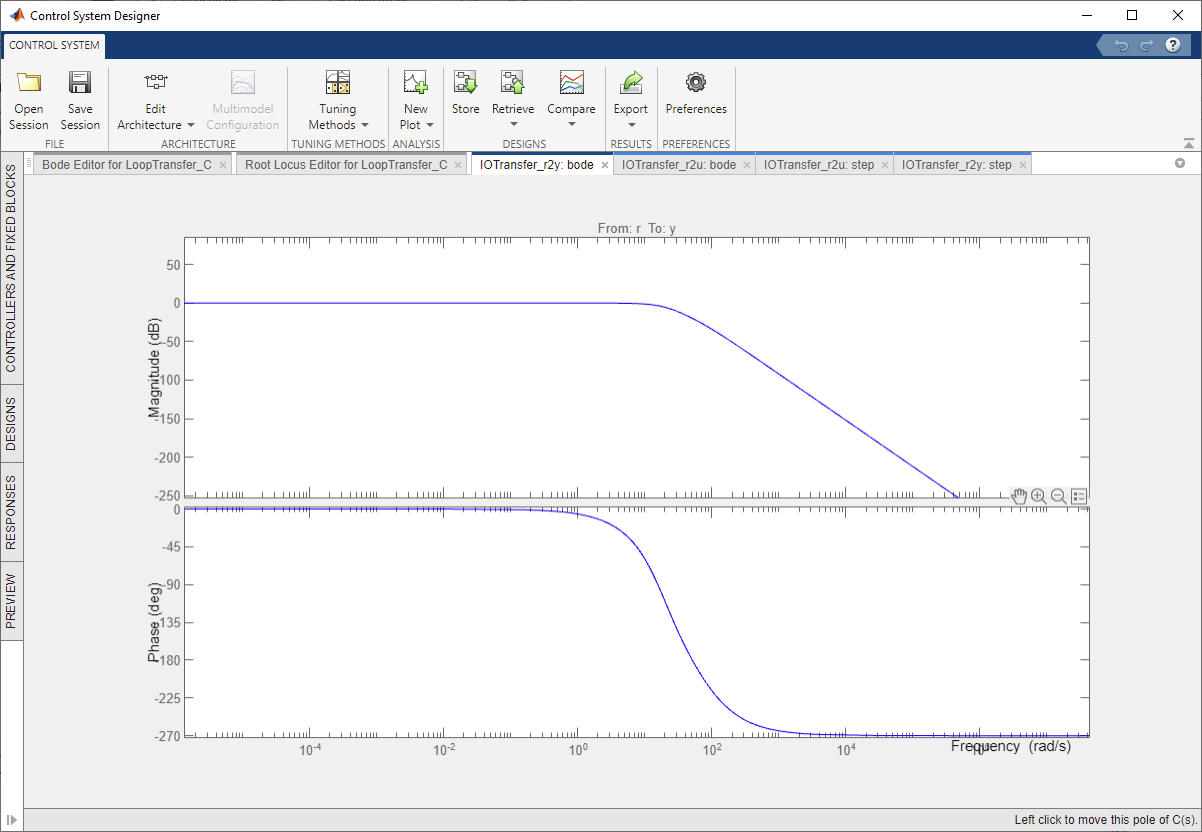

## Closed Loop analysis

load('Reg_Fede.mat');
R4 = R; % regulator
R_tf = tf(R4); % convert in tf

### Loop tf

L = R4*G_th % loop tf L(s)

L =
 
                                                                 
   25270 (s+16.24) (s^2 + 0.4572s + 42.42) (s^2 + 0.793s + 43.11)
                                                                 
  -----------------------------------------------------------------
                                                                   
  s (s+44.73) (s+58.62) (s+16.25) (s^2 + 0.4579s + 42.42)          
                                                                   
                                            (s^2 + 0.7921s + 43.12)
                                                                   
 
Continuous-time zero/pole/gain model.



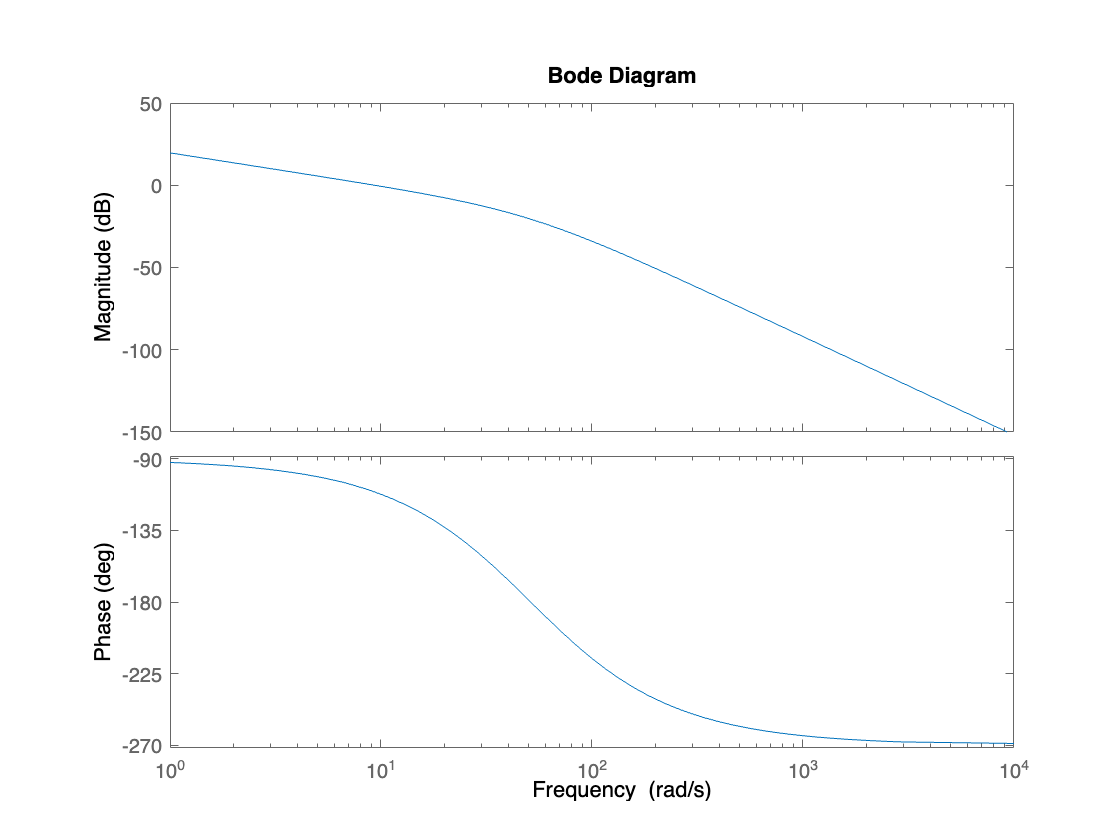

bode(L)

[Gm_L,Pm_L,WcG_L,Wcp_L] = margin(L)

Gm_L = 10.7242

Pm_L = 69.2009

WcG_L = 51.2072

Wcp_L = 9.3195

dcgain(L)

ans = Inf

## Sensitivity tf

### Complementary Sensitivity $F\left(s\right)$:

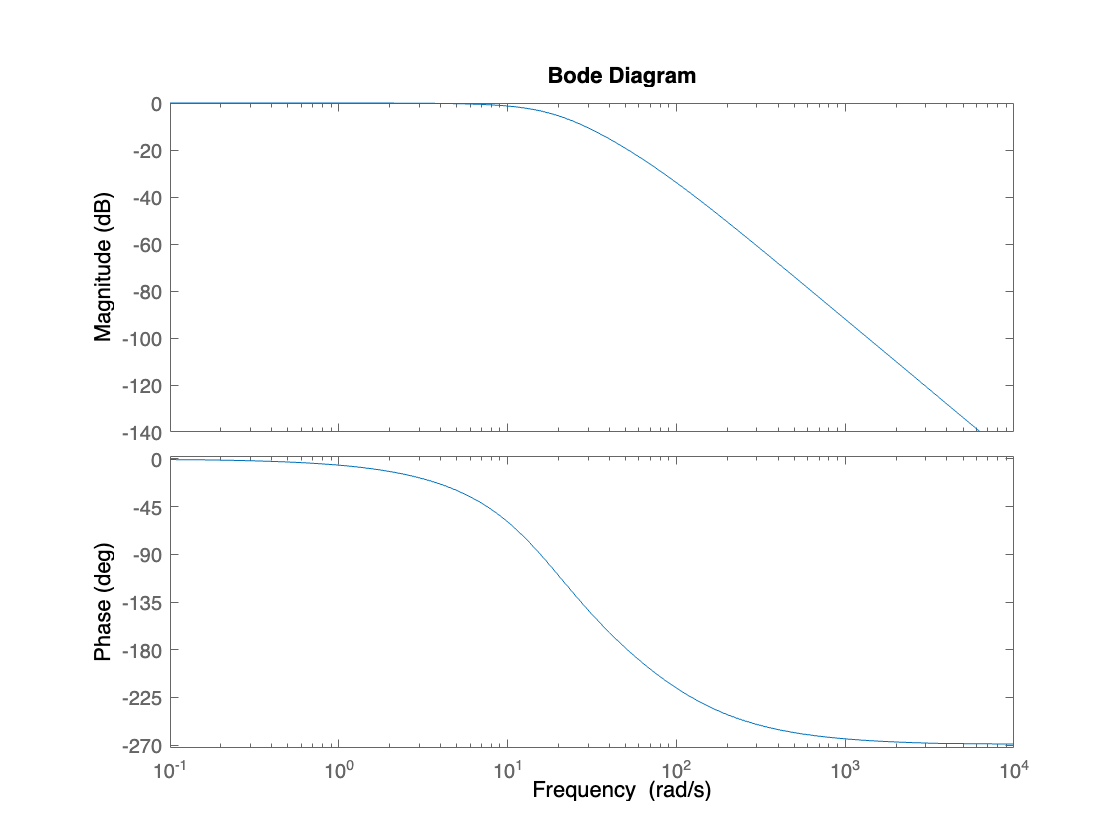

F = L/(1+L);
bode(F)

[~,Pm_F,~,Wcp_F] = margin(F)

Pm_F = -180

Wcp_F = 0

dcgain(F)

ans = 1.0000

bw_F = bandwidth(F)

bw_F = NaN

The bandwidth of F is approximately $\omega =14\ldotp 7594\;\frac{\textrm{rad}}{s}$

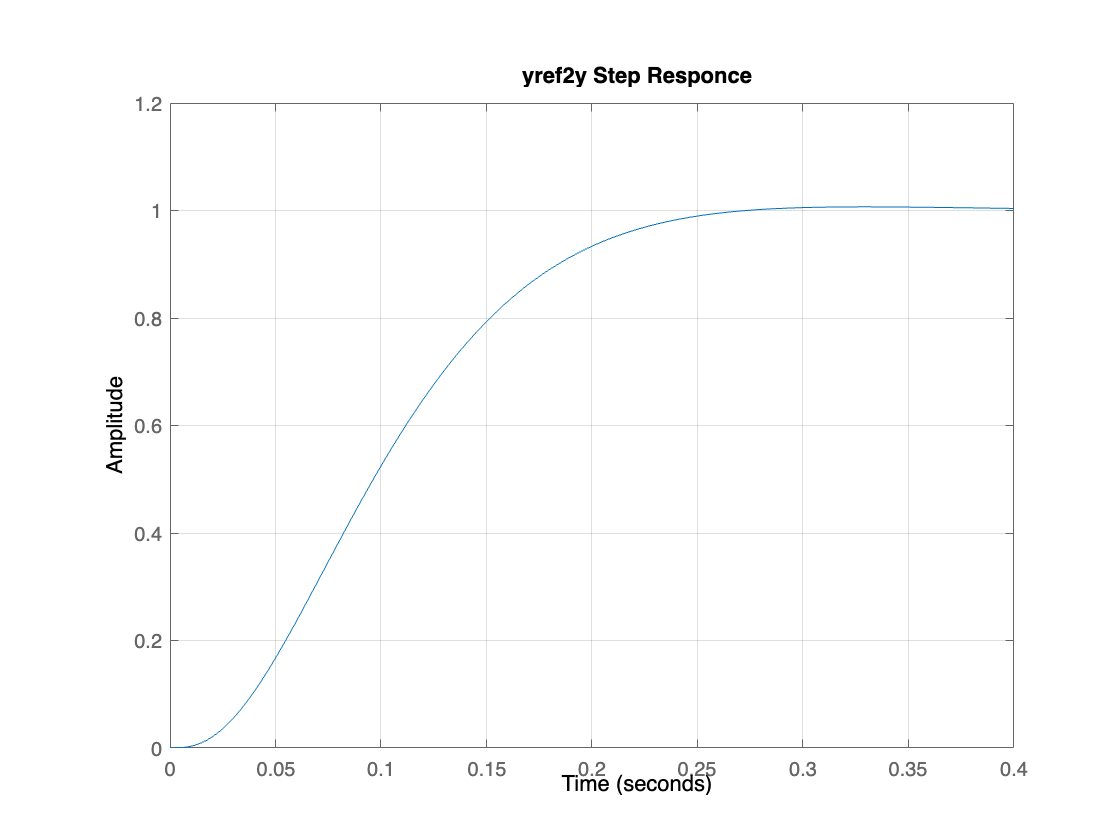

step(F); grid on; title('yref2y Step Responce')

stepinfo(F)

ans = struct with fields:
         RiseTime: 0.1449
    TransientTime: 0.2366
     SettlingTime: 0.2366
      SettlingMin: 0.9053
      SettlingMax: 1.0068
        Overshoot: 0.6676
       Undershoot: 0
             Peak: 1.0068
         PeakTime: 0.3286


### Sensitivity $S\left(s\right)$:

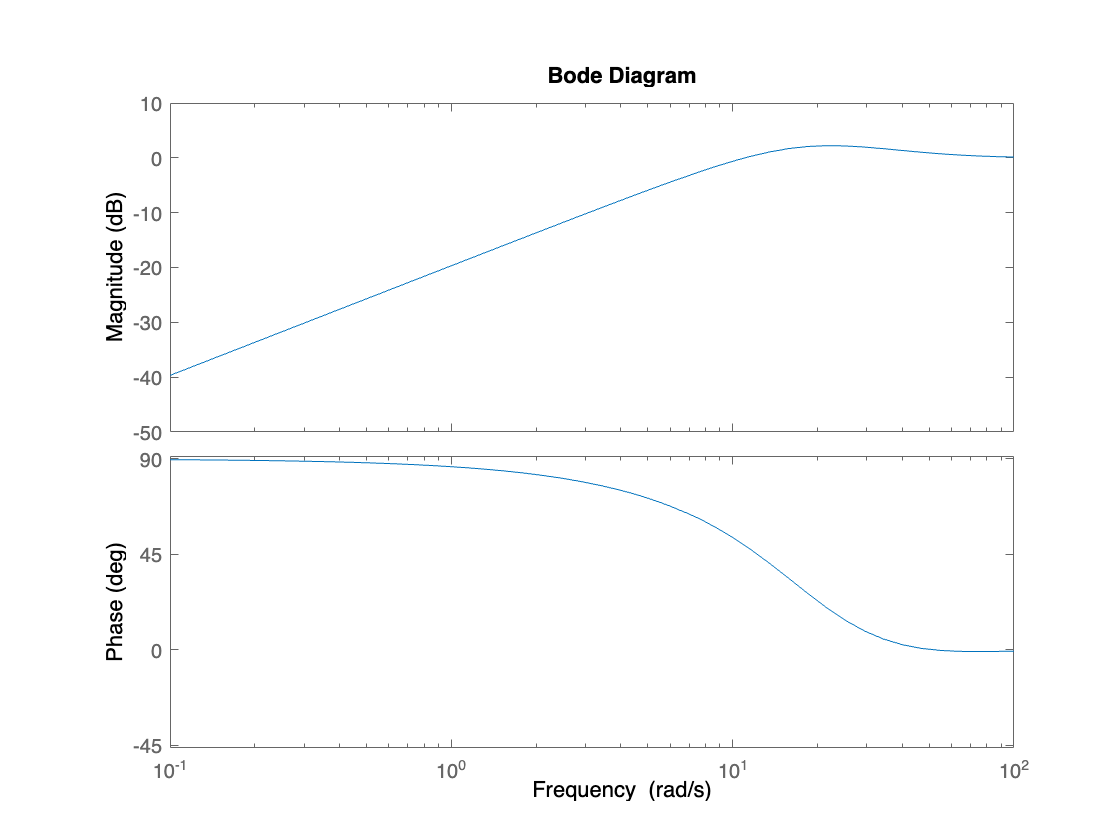

S = 1/(1+L);
bode(S)

[~,Pm_S,~,Wcp_S] = margin(S)

Pm_S = -130.8695

Wcp_S = 11.0580

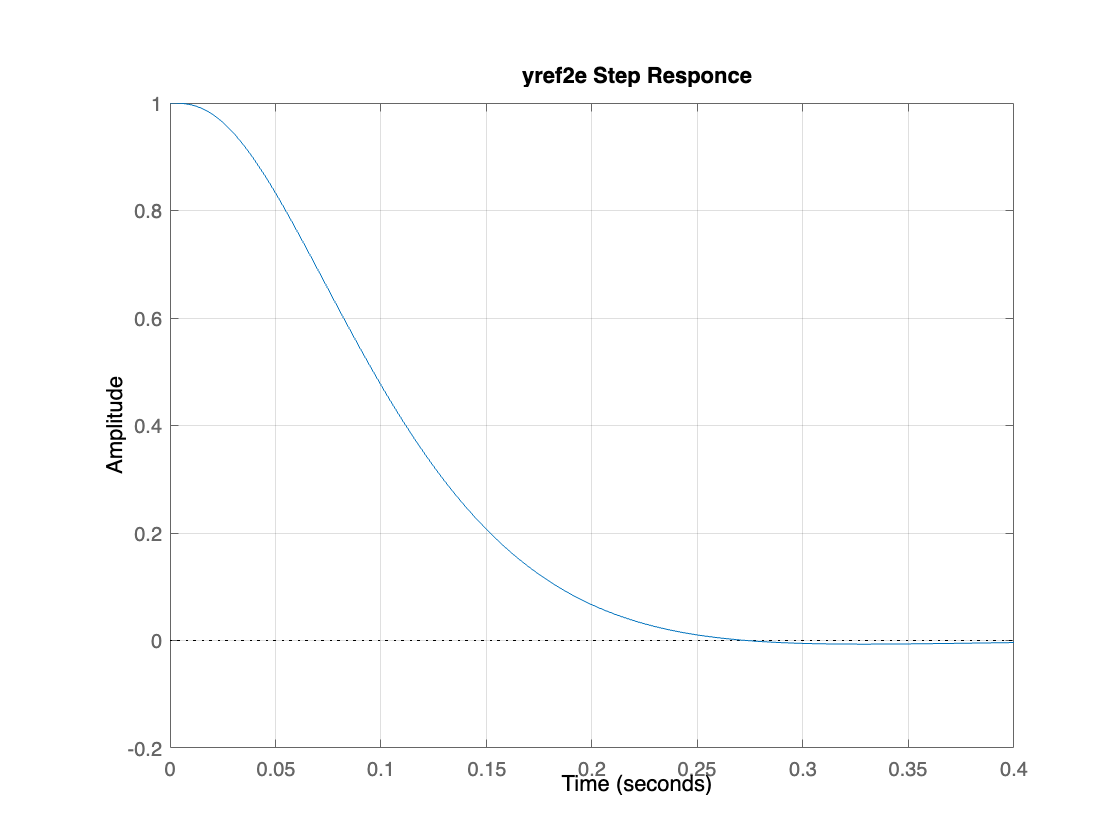

step(S); grid on; title('yref2e Step Responce')

stepinfo(S)

ans = struct with fields:
         RiseTime: 2.2204e-15
    TransientTime: 0.2365
     SettlingTime: NaN
      SettlingMin: -0.0068
      SettlingMax: -8.3046e-05
        Overshoot: 7.6089e+14
       Undershoot: 1.1259e+17
             Peak: 1
         PeakTime: 0


### Control Sensitivity $Q\left(s\right)=R\left(s\right)S\left(s\right)$:

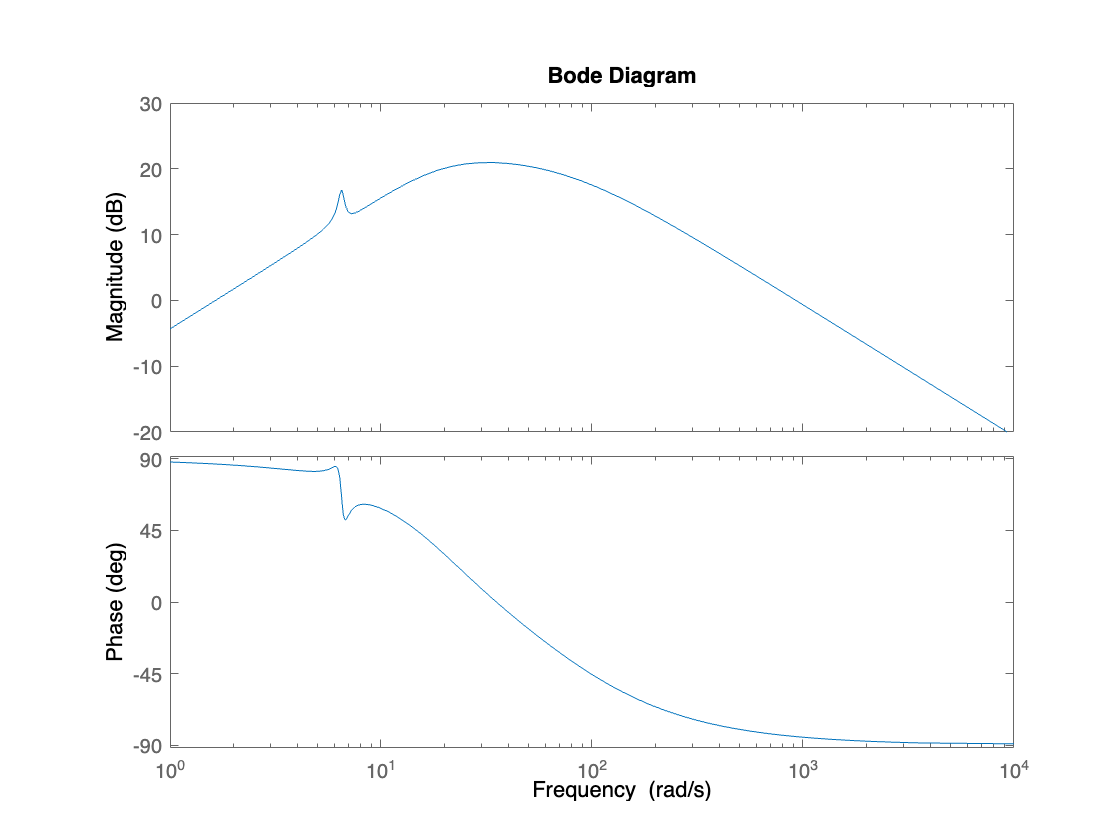

Q = R*S;
bode(Q)

[~,Pm_Q,~,Wcp_Q] = margin(Q)

Pm_Q = -93.2405

Wcp_Q = 1.6431

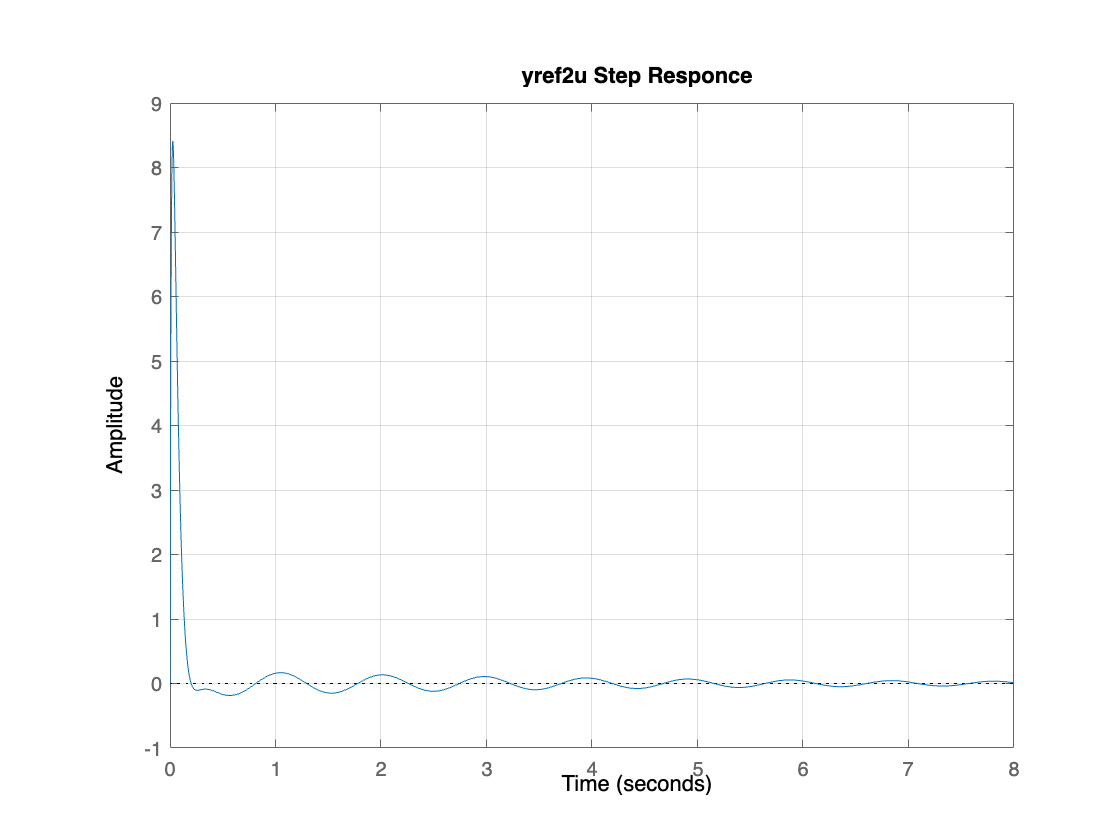

step(Q); grid on; title('yref2u Step Responce')

stepinfo(Q)

ans = struct with fields:
         RiseTime: 1.1102e-16
    TransientTime: 0.6341
     SettlingTime: NaN
      SettlingMin: -0.1856
      SettlingMax: 0.1675
        Overshoot: 2.9067e+16
       Undershoot: 1.3176e+18
             Peak: 8.4114
         PeakTime: 0.0270


## Closed Loop from yref to alpha.

F_alpha = R*G_alpha/(1+L)

F_alpha =
 
                                                                             
  -23602 s^2 (s+16.24) (s+16.25) (s+44.73) (s+58.62) (s^2 + 0.4579s + 42.42) 
                                                                             
                     (s^2 + 0.793s + 43.11) (s^2 + 0.7921s + 43.12)          
                                                                             
  ---------------------------------------------------------------------------
                                                                            
  (s+44.73) (s+58.62) (s+71.69) (s+16.25) (s+16.23) (s^2 + 0.4574s + 42.42) 
                                                                            
          (s^2 + 0.4579s + 42.42) (s^2 + 0.794s + 43.12)                    
                                                                            
                     (s^2 + 0.7921s + 43.12) (s^2 + 31.67s + 352.7)         
                                                          

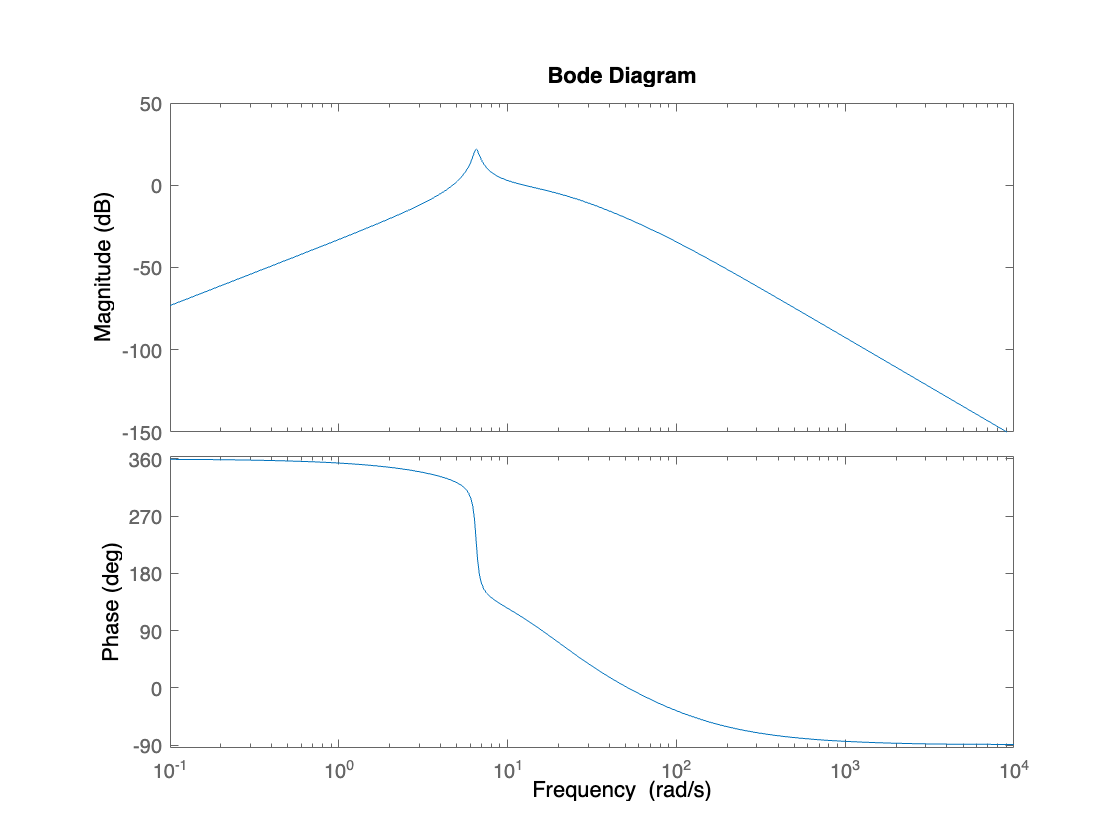

bode(F_alpha)

[~,Pm_F_alpha,~,Wcp_F_alpha] = margin(F_alpha)

Pm_F_alpha = -71.0227

Wcp_F_alpha = 12.5655

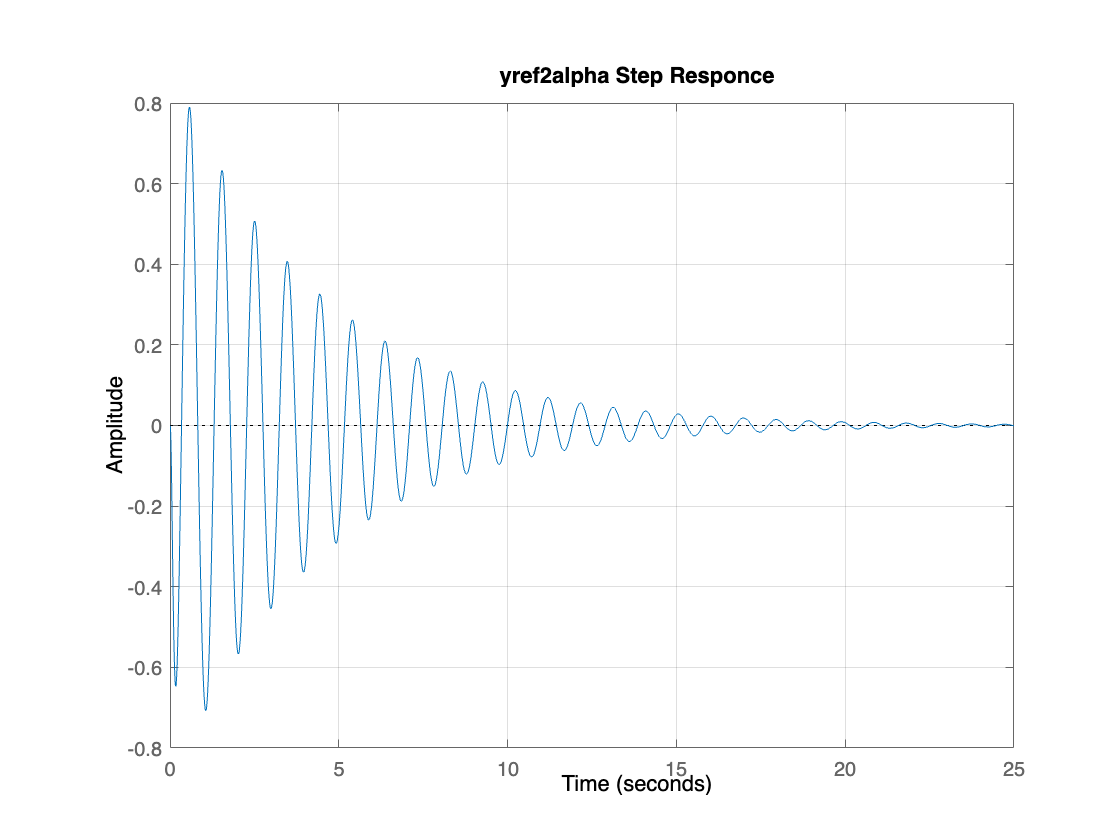

step(F_alpha); grid on; title('yref2alpha Step Responce')

stepinfo(F_alpha)

ans = struct with fields:
         RiseTime: 1.7347e-18
    TransientTime: 17.5159
     SettlingTime: NaN
      SettlingMin: -0.7075
      SettlingMax: 0.7902
        Overshoot: 3.2955e+20
       Undershoot: 3.6807e+20
             Peak: 0.7902
         PeakTime: 0.5759


% % ~ Alberto
% % Overshoot of 3.5%, settling time 0.131, rise time 0.032
% R1 = zpk([-15 -40],[-55 -60],143); % Nel toolbox gain = 26
% L1 = R1*tf_sys(1)/(1+R1*tf_sys(1));
% step(L1); grid on; title('R_1 Step Responce')
% stepinfo(L1);
% 
% % ~ Alberto
% % % Overshoot of 0%, settling time 0.474, rise time 0.0217
% R2 = zpk([-7 -50],[-70 -60],96); % Nel toolbox gain = 8
% L2 = R2*tf_sys(1)/(1+R2*tf_sys(1));
% % step(L2); grid on; title('R_2 Step Responce')
% stepinfo(L2);
% 
% % ~ Simone
% R3 = zpk((-3e7/1.5e6),(-100000),1.5e6);
% L3 = R3*tf_sys(1)/(1+R3*tf_sys(1));
% % step(L3); grid on; title('R_3 Step Responce')
% stepinfo(L3);